bridgeobj = OriginalBridges(1);
% Girder
class_plot = 'Girder';
girders = bridgeobj.findStructureByClass(class_plot);
elems_force = [];
for i=1:length(girders)
    girder = girders{i};
    elems_force = [elems_force,girder.Element];
end
sorted_elems_force = elems_force.sortByCenterPoint("X");

fig = figure;
ax = axes;
bridgeobj.plot("Figure",fig,'Axis',ax)
hold(ax,'on')
type_elems = class_plot;
type_force = 'My';
[InternalForce_i,InternalForce_j] = getInternalForce(sorted_elems_force,type_force)
[fig,ax] = getBeamElementGlobalForce(sorted_elems_force,type_elems,InternalForce_i,InternalForce_j,...
                                     'Pattern','plot3',...
                                     'Figure',fig,...
                                     'Axis',ax,...
                                     'Scale', 50/max(abs([InternalForce_i,InternalForce_j])))
view([0,-1,0])

% Tower
class_plot = 'Tower';
girders = bridgeobj.findStructureByClass(class_plot);
elems_force = girders{1}.Element;
sorted_elems_force = elems_force.sortByCenterPoint("Z");

fig = figure;
ax = axes;
bridgeobj.plot("Figure",fig,'Axis',ax)

C = 'g'

C = 'g'

C = 'g'

C = 'g'

C = 'g'

C = 'g'

C =     0.9098    0.5451         0


C =     0.9098    0.5451         0


C =     0.9098    0.5451         0


C =     0.9098    0.5451         0


C =     0.9098    0.5451         0


C =     0.9098    0.5451         0


C =     0.9098    0.5451         0


ans =   Figure (79) - 属性:

      Number: 79
        Name: ''
       Color: [1 1 1]
    Position: [440 338 560 420]
       Units: 'pixels'

  显示 所有属性


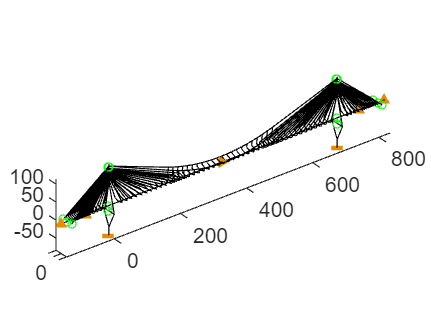

hold(ax,'on')

type_elems = class_plot;
type_force = 'My';
type_plot = 'plot';
[InternalForce_i,InternalForce_j] = getInternalForce(sorted_elems_force,type_force)

InternalForce_i = 1.0e+08 *

   -1.4275   -1.3732   -1.3147   -1.2524   -1.1864   -0.4684   -0.4684   -0.3999   -0.3999   -0.3291   -0.3291   -0.2565   -0.2565   -0.1826   -0.1826         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.1133   -0.1133    0.0174    0.0174    0.1461    0.1461    0.2711    0.2711    0.3907    0.3907    0.8119    0.8390    0.8658    0.8922    0.9184


InternalForce_j = 1.0e+08 *

   -1.4775   -1.4275   -1.3731   -1.3147   -1.2524   -0.5338   -0.5338   -0.4683   -0.4683   -0.3999   -0.3999   -0.3291   -0.3291   -0.2564   -0.2564         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0   -0.2439   -0.2439   -0.1131   -0.1131    0.0176    0.0176    0.1463    0.1463    0.2712    0.2712    0.7845    0.8119    0.8390    0.8658    0.8922


[fig,ax] = getBeamElementGlobalForce(sorted_elems_force,type_elems,InternalForce_i,InternalForce_j,...
                                     'Pattern','plot3',...
                                     'Figure',fig,...
                                     'Axis',ax,...
                                     'Scale', 20/max(abs([InternalForce_i,InternalForce_j])))

错误使用 test_plotInternalForce>getBeamElementGlobalForce
位置 3 处的参数无效。 函数要求名称 'Pattern' 之前恰好有 2 个位置输入。

view([0,-1,0])

function [fig,ax] = getBeamElementGlobalForce(elems_force,type_elems,options)
    arguments
        elems_force % 按照顺序排列
        type_elems {mustBeMember(type_elems,{'Girder','Tower'})}
        options.Pattern {mustBeMember(options.Pattern,{'bar','plot3'})} = 'plot3'
        options.Scale = 1e-8
        options.Figure = figure
        options.Axis = axes
    end
    % 思路：
    %   1. 假设：用于Girder的内力，方向都是水平，没有上下高差
    %   2. 假设：用于Tower的内力，方向都是竖直，没有水平变化
    %   3. 内力作图的通用方法：[单元1在节点A处内力,单元1的IJ节点内力均值,...,单元n-1的IJ节点内力均值，单元n在节点B处内力]
    %   4. 两种作图形式：直方图(bar和barh)，三维曲线(plot3)
    fig = options.Figure;
    ax = options.Axis;
    figure(fig)

    [InternalForce_i,InternalForce_j] = getInternalForce(sorted_elems_force,type_force)
    switch options.Pattern
        case 'bar'
            if strcmp(type_elems,'Girder')
            elseif strcmp(type_elems,'Tower')
            end
            
        case 'plot3'
            InternalForce = [InternalForce_i(1),(InternalForce_i + InternalForce_j)/2,InternalForce_j(end)];
            if strcmp(type_elems,'Girder')
                PostionX = [inodes(1).X,([inodes.X] + [jnodes.X])/2,jnodes(end).X];
                PostionY = [inodes(1).Y,([inodes.Y] + [jnodes.Y])/2,jnodes(end).Y];
                PostionZ = [inodes(1).Z,([inodes.Z] + [jnodes.Z])/2,jnodes(end).Z] + options.Scale*InternalForce;
            elseif strcmp(type_elems,'Tower')
                PostionX = [inodes(1).X,([inodes.X] + [jnodes.X])/2,jnodes(end).X] + options.Scale*InternalForce;
                PostionY = [inodes(1).Y,([inodes.Y] + [jnodes.Y])/2,jnodes(end).Y];
                PostionZ = [inodes(1).Z,([inodes.Z] + [jnodes.Z])/2,jnodes(end).Z];
            end
            plot3(ax,PostionX,PostionY,PostionZ)
            
    end
end
function [InternalForce_i,InternalForce_j] = getInternalForce(elems_force,type_force)
    arguments
        elems_force % 按照顺序排列
        type_force {mustBeMember(type_force,{'Fx','My'})}
    end
    switch type_force
        case 'Fx'
            Force_Force_LocalCoord = [elems_force.Force_LocalCoord];
            InternalForce_i = Force_Force_LocalCoord(1,:);
            InternalForce_j = Force_Force_LocalCoord(7,:);
        case 'My'
            Force_Force_LocalCoord = [elems_force.Force_LocalCoord];
            Myi = Force_Force_LocalCoord(5,:);
            Myj = Force_Force_LocalCoord(11,:);
            Mzi = Force_Force_LocalCoord(6,:);
            Mzj = Force_Force_LocalCoord(12,:);
            [~,Comp_y,Comp_z] = elems_force.getLocalCoordSystemComponent([0,1,0]);
            InternalForce_i = Myi.*Comp_y' + Mzi.*Comp_z';
            InternalForce_j = Myj.*Comp_y' + Mzj.*Comp_z';
    end
end